# COTS Ensemble Live Script 23

## Set Interpreter

setInterpLatex()

## Contents

Distance-based Connectivity Comparison

Network theory metrics - maximum values

Extra network theory metrics

## Assumptions

## Network theory metrics - maximum values

% need to now form yearly global matrices
conMatGlobYearly = cell(1, 5);
for i = 1:length(conMatsSeasSlim)
    conMatGlobYearly{i} = zeros(nReefs, nReefs);
    if i == 5
        conMatGlobYearly{i} = (conMatsSeasGbrlDp{5} ...
            + conMatsSeasGbrlUp{5} + conMatsSeasSlim{5}) / 3;
        continue
    end
    conMatGlobYearly{i} = (conMatsSeasGbrlDp{i} ...
            + conMatsSeasGbrlUp{i} + conMatsSeasSlim{i} ...
            + conMatsSeasGbr1{i}) / 4;
    conMatGlobYearly{i} = sparse(conMatGlobYearly{i});
end

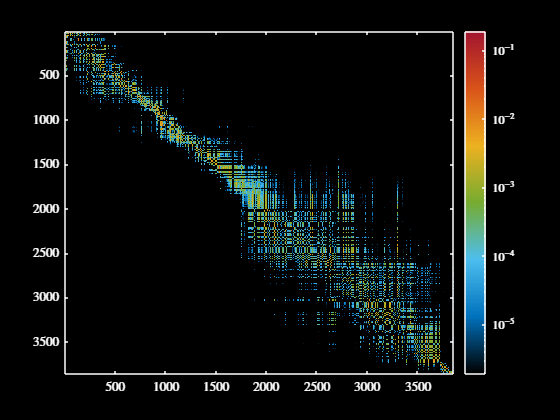

% let's make sure they look normal
figure
for i = 1:5
    clf
    imagesc(conMatGlobYearly{i}(sortLat3861, sortLat3861))
    colormap(myColourMap())
    set(gca, 'colorscale', 'log')
    colorbar()
    darkFig()
    saveFig("fig" + i)
end

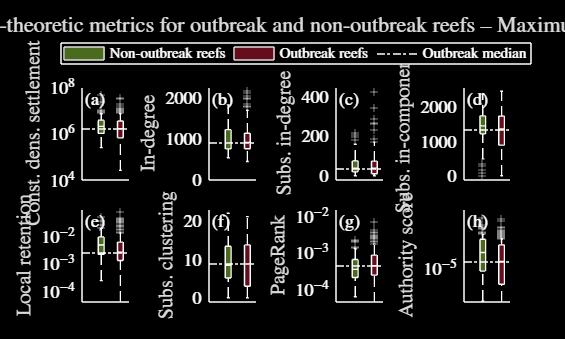

Const. dens. settlement
Mean non-outbreaks: 

ans = 3.2605e+06

Mean outbreaks: 

ans = 2.7956e+06

KS test

p = 0.0422

Median test

p = 0.1385

--------------------------------------------------
In-degree
Mean non-outbreaks: 

ans = 992.8889

Mean outbreaks: 

ans = 988.9541

KS test

p = 0.6322

Median test

p = 0.7797

--------------------------------------------------
Subs. in-degree
Mean non-outbreaks: 

ans = 54.1889

Mean outbreaks: 

ans = 54.0530

KS test

p = 0.2987

Median test

p = 0.7797

--------------------------------------------------
Subs. in-component
Mean non-outbreaks: 

ans = 1.3688e+03

Mean outbreaks: 

ans = 1.2325e+03

KS test

p = 0.0177

Median test

p = 0.3186

--------------------------------------------------
Local retention
Mean non-outbreaks: 

ans = 0.0072

Mean outbreaks: 

ans = 0.0061

KS test

p = 0.0019

Median test

p = 0.0071

--------------------------------------------------
Subs. clustering
Mean non-outbreaks: 

ans = 9.3669

Mean outbreaks: 

ans = 8.6069

KS test

p = 0.1040

Median test

p = 0.8315

--------------------------------------------------
PageRank
Mean non-outbreaks: 

ans = 4.9635e-04

Mean outbreaks: 

ans = 6.8977e-04

KS test

p = 0.1416

Median test

p = 0.0959

--------------------------------------------------
Authority score
Mean non-outbreaks: 

ans = 0.0012

Mean outbreaks: 

ans = 6.1567e-04

KS test

p = 0.0017

Median test

p = 0.0273

--------------------------------------------------


% let's redo the network theory stuff, but using the maximum values
% temporally
% let's redo figures with different graph-theoretic metrics
var1 = ["", "DM"];
figure
for i = 1:2
    clf()
    plotLarvalSupply(cotsDensBrt, conMatGlobYearly, ...
        nonOutbrReefs, outbrReefs, "Graph-theoretic metrics for " + ...
        "outbreak and non-outbreak reefs -- Maximum values", ...
        i == 2, false, "conMax")
    saveFig("graphTheoryMetricsMax" + var1(i))
end

## Extra network theory metrics

% let's just screw around with a random network rq, or like a subset of the
% global connectivity matrix might be better

% want to look at some additional network theoretic metrics that I could
% add in
reefInds = 1:100:1000;
var1 = full(conMatGlobal(reefInds, reefInds))

var1 =     0.0047    0.0000    0.0000    0.0001    0.0000         0         0         0         0         0
    0.0000    0.0007    0.0000         0    0.0000    0.0000         0         0         0         0
    0.0000    0.0000    0.0073    0.0000    0.0001    0.0000    0.0000         0         0         0
    0.0000    0.0000    0.0000    0.0072    0.0000    0.0000    0.0000         0         0         0
         0    0.0000    0.0042         0    0.0002    0.0000    0.0000         0         0         0
    0.0000    0.0000    0.0005    0.0001    0.0000    0.0001    0.0000         0         0    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0065         0         0    0.0000
         0         0         0         0         0         0    0.0000    0.0009    0.0000    0.0001
         0         0         0         0         0         0         0    0.0000    0.0057    0.0001
         0         0    0.0000         0         0    0.0000    0.0000    0.0001    

sum(sum(var1 == 0))

ans = 42


% ok cool

% need to use a digraph if you have weighted edges
var2 = digraph(var1)

var2 =   digraph with properties:

    Edges: [58×2 table]
    Nodes: [10×0 table]



% figure out if it's costly to set up the graphs
tic
digraph(conMatGlobal)

ans =   digraph with properties:

    Edges: [4593564×2 table]
    Nodes: [3861×0 table]


toc

Elapsed time is 0.253783 seconds.


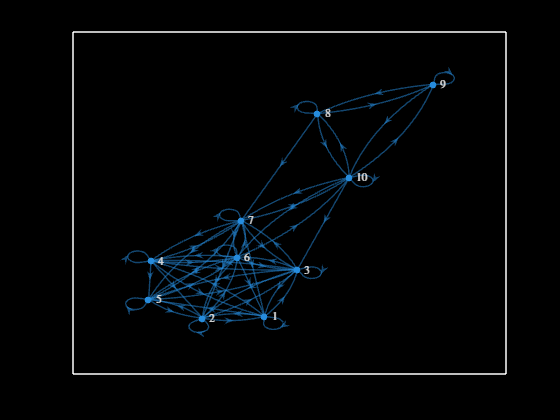


% ok sweet so it's quick to turn the massive matrices into digraphs epic
figure
plot(var2)
darkFig()

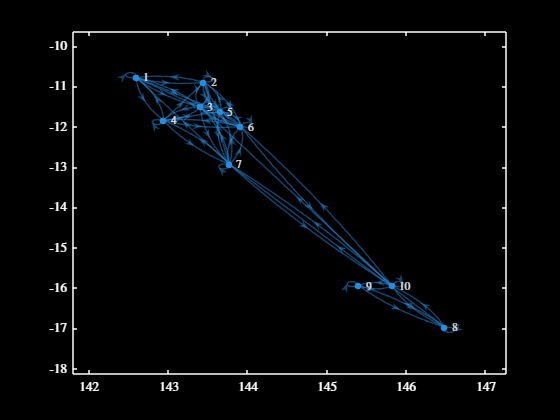

% saveCoolFig("graphImage")

% let's do another plot of the actual spatial location
figure
plot(var2, 'XData', centroidsLL(reefInds, 1), 'YData', ...
    centroidsLL(reefInds, 2))
darkFig()


% let's make sure that the links are correct I suppose
var2.Edges

ans = 58×2 table
    EndNodes      Weight  
    ________    __________

     1    1       0.004693
     1    2     9.8289e-09
     1    3     1.0861e-05
     1    4     8.7126e-05
     1    5     1.4253e-08
     2    1     6.1636e-06
     2    2     0.00069024
     2    3     2.4305e-06
     2    5      3.354e-06
     2    6     2.9828e-09
     3    1     4.9605e-07
     3    2     4.8737e-05
     3    3      0.0073242
     3    4     1.4205e-09
     3    5     0.00013402
     3    6     6.9871e-07


var1(1, 1)

ans = 0.0047

var1(1, 5)

ans = 1.4253e-08

var1(2, 3)

ans = 2.4305e-06

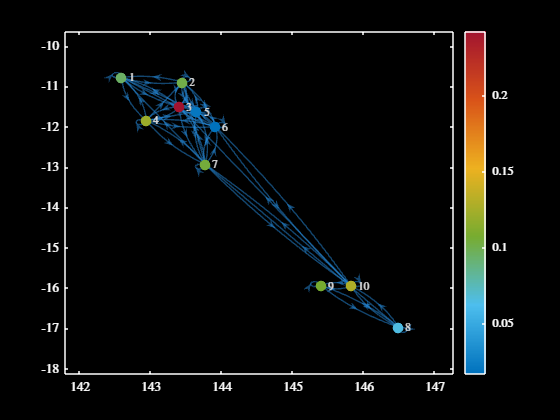


% alright, looks good, let's try calculate a few different metrics just for
% fun an eyeball them
var3 = centrality(var2, 'pagerank', 'Importance', var2.Edges.Weight);
figure
p = plot(var2, 'XData', centroidsLL(reefInds, 1), 'YData', ...
    centroidsLL(reefInds, 2), 'MarkerSize', 7);
p.NodeCData = var3;
colormap(myColourMap("dmTurbo"))
colorbar()
darkFig()

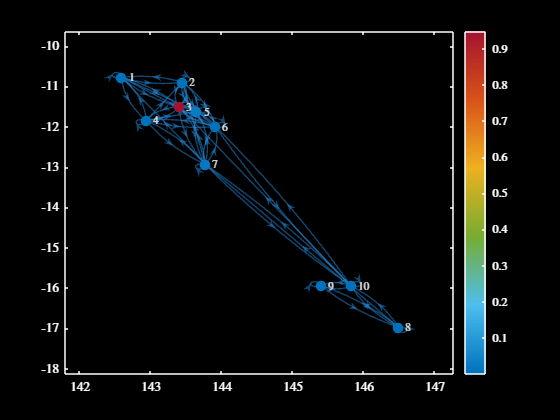


% let's also do authorities
var3 = centrality(var2, 'authorities', 'Importance', var2.Edges.Weight);
figure
p = plot(var2, 'XData', centroidsLL(reefInds, 1), 'YData', ...
    centroidsLL(reefInds, 2), 'MarkerSize', 7);
p.NodeCData = var3;
colormap(myColourMap("dmTurbo"))
colorbar()
darkFig()

sum(var3)

ans = 1.0000

sum(var1, 2)

ans =     0.0048
    0.0007
    0.0075
    0.0072
    0.0045
    0.0007
    0.0066
    0.0010
    0.0058
    0.0076


sum(var1, 1)

ans =     0.0047    0.0008    0.0121    0.0074    0.0004    0.0001    0.0066    0.0010    0.0059    0.0076


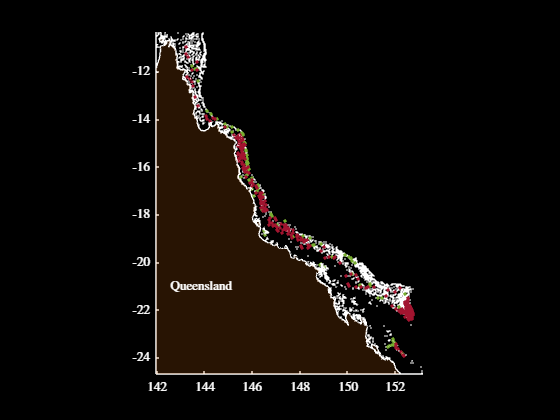

% let's look at the spatial distribution of the outbreak and non-outbreak
% reefs
figure
hold on
plotPoints(centroidsLL, 'markerSize', 0.5)
plotPoints(centroidsLL(nonOutbrReefs, :), 'colour', 'g', 'markerSize', 8)
plotPoints(centroidsLL(outbrReefs, :), 'colour', 'r', 'markerSize', 8)
plotQldOutline(qldOutline)
axis equal
axis(gbrBoundaryLL)
darkFig()


% let's figure out how many are in the initiation box
sum((centroidsLL(nonOutbrReefs, 2) > -16) ...
    .* (centroidsLL(nonOutbrReefs, 2) < -14.5) == 1)

ans = 16

sum((centroidsLL(outbrReefs, 2) > -16) ...
    .* (centroidsLL(outbrReefs, 2) < -14.5) == 1)

ans = 55


% alright - too few in my opinion to analyse the initation box